## Initialize

clear all;

addpath(genpath('matlabfunctions'))
addpath(genpath('/Applications/MATLAB_TOOLBOXES'))

area_metric = 3;


## Load & Format Macaque Data

load('./completeData/monkey_data')

% these numbers correspond to color-coded grouping of brain areas in plots
EVCrois_monkey=1:3; EVCcolor=[0.1 0.6 1];
V4rois_monkey=4:5; V4color=[1 0.2 1];
ventralrois_monkey=6:10; ventralcolor=[1 0.2 0.2];
dorsalrois_monkey=11:12; dorsalcolor=[1 .8 0];
lateralrois_monkey=13:16; lateralcolor=[0 1 0];
parietalrois_monkey=17:21; parietalcolor=[0 1 1];

% concatenate all human area ROIs, labels, and colors
region_rois_monkey = {EVCrois_monkey;V4rois_monkey;ventralrois_monkey;dorsalrois_monkey;parietalrois_monkey;lateralrois_monkey};
colorscale_monkey_all=[repmat(EVCcolor,length(EVCrois_monkey),1);...
    repmat(V4color,length(V4rois_monkey),1);...
    repmat(ventralcolor,length(ventralrois_monkey),1);...
    repmat(dorsalcolor,length(dorsalrois_monkey),1);...
    repmat(lateralcolor,length(lateralrois_monkey),1);...
    repmat(parietalcolor,length(parietalrois_monkey),1)];

colorscale_monkey_all_inv = flipud(colorscale_monkey_all);
colorscale_region_monkey=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor];
colorscale_unique_monkey = unique(colorscale_region_monkey,'stable','rows');
colorscale_region_monkey_inv = flipud(colorscale_region_monkey);

% rename areas to match human code
for i = 1:2
    surfacearea_monkey_total{i} = monkey_data.retino_surfacearea_total{i};
    surfacearea_smoothwm{i} = monkey_data.retino_surfacearea_smoothwm{i};
    surfacearea_pial{i} = monkey_data.retino_surfacearea_pial{i};
end
% sum over hemispheres
total_surfacearea_bothhemis=surfacearea_monkey_total{1}+surfacearea_monkey_total{2};

% actual full brain surface area
total_area_cat_monkey = [monkey_data.total_size(:,1)' monkey_data.total_size(:,2)'];
total_area_sum_monkey = monkey_data.total_size(:,1)' + monkey_data.total_size(:,2)';

% Make 0 sum ROIs -> NaN
for i = 1:2
    surfacearea_smoothwm{i}(surfacearea_smoothwm{i}==0)=nan;
    surfacearea_pial{i}(surfacearea_pial{i}==0)=nan;
end
% get average of white matter and pial surface area
surfacearea_avg = cellfun(@(x,y) (x+y)/2, surfacearea_smoothwm, surfacearea_pial,'UniformOutput',false);

% get sum and concatenated hemispheres depending on area metric
if area_metric == 1
    % use this for WM 
    surfacearea_bothhemis_monkey = surfacearea_smoothwm{1} + surfacearea_smoothwm{2};
    surfacearea_catbothhemis_monkey=cat(2,surfacearea_smoothwm{1},surfacearea_smoothwm{2});
    surfacearea_monkey = surfacearea_smoothwm;
elseif area_metric ==2
    % use this for pial 
    surfacearea_bothhemis_monkey = surfacearea_pial{1} + surfacearea_pial{2};
    surfacearea_catbothhemis_monkey=cat(2,surfacearea_pial{1},surfacearea_pial{2});
    surfacearea_monkey = surfacearea_pial;
elseif area_metric == 3
    % use this for average of WM and pial surface
    surfacearea_catbothhemis_monkey = cat(2,surfacearea_avg{1},surfacearea_avg{2});
    surfacearea_bothhemis_monkey = surfacearea_avg{1} + surfacearea_avg{2};
    surfacearea_monkey = surfacearea_avg;
end

% restructure data for concatenated hemis
V1_bothhemis_combined = surfacearea_catbothhemis_monkey(1,:) + surfacearea_catbothhemis_monkey(2,:);
V2_bothhemis_combined = sum(surfacearea_catbothhemis_monkey(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_catbothhemis_monkey(5:6,:),1);
V4_bothhemis_combined = sum(surfacearea_catbothhemis_monkey(7:8,:),1);
V4A_bothhemis_combined = sum(surfacearea_catbothhemis_monkey(9:10,:),1);

cat_monkey = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;V4A_bothhemis_combined;surfacearea_catbothhemis_monkey(11:end,:)];

% restructure data to get area categories we want to display
V1_bothhemis_combined = surfacearea_bothhemis_monkey(1,:) + surfacearea_bothhemis_monkey(2,:);
V2_bothhemis_combined = sum(surfacearea_bothhemis_monkey(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_bothhemis_monkey(5:6,:),1);
V4_bothhemis_combined = sum(surfacearea_bothhemis_monkey(7:8,:),1);
V4A_bothhemis_combined = sum(surfacearea_bothhemis_monkey(9:10,:),1);

sum_monkey = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;V4A_bothhemis_combined;surfacearea_bothhemis_monkey(11:end,:)];

% average over broad areas for raw surface area measurements
V4_combined_monkey = mean(sum_monkey(4:5,:),1);
ventral_combined_monkey = mean(sum_monkey(ventralrois_monkey-5,:),1);
dorsal_combined_monkey = mean(sum_monkey(dorsalrois_monkey-5,:),1);
lateral_combined_monkey = mean(sum_monkey(lateralrois_monkey-5,:),1);
parietal_combined_monkey = mean(sum_monkey(parietalrois_monkey-5,:),1);

region_monkey = [sum_monkey(1:3,:);V4_combined_monkey;ventral_combined_monkey;...
    dorsal_combined_monkey;lateral_combined_monkey;parietal_combined_monkey];

%combined hemis V1
normv1_monkey = sum_monkey./V1_bothhemis_combined;

% average over broad regions for surface area measurements relative to V1
normV4_combined_monkey = mean(normv1_monkey(4:5,:),1);
normventral_combined_monkey = mean(normv1_monkey(ventralrois_monkey-5,:),1);
normdorsal_combined_monkey = mean(normv1_monkey(dorsalrois_monkey-5,:),1);
normlateral_combined_monkey = mean(normv1_monkey(lateralrois_monkey-5,:),1);
normparietal_combined_monkey = mean(normv1_monkey(parietalrois_monkey-5,:),1);

region_monkey_normv1 = [normv1_monkey(1:3,:);normV4_combined_monkey;normventral_combined_monkey;...
    normdorsal_combined_monkey;normlateral_combined_monkey;normparietal_combined_monkey];

alllabels_monkey = cat(2,{'V1','V2','V3','V4','V4A'},monkey_data.labels(11:end));
alllabels_monkey_region = {'V1','V2','V3','V4','Ventral','Dorsal','Lateral','Parietal'};

human_blue = [0 0.4470 0.7410];
monkey_orange = [0.8500 0.3250 0.0980];

## Load & Format Adult Human Data

load('./completeData/human_data')

disp(human_data.labels)

  Columns 1 through 13

    {'V1v'}    {'V1d'}    {'V2v'}    {'V2d'}    {'V3v'}    {'V3d'}    {'hV4'}    {'VO1'}    {'VO2'}    {'PHC1'}    {'PHC2'}    {'V3A'}    {'V3B'}

  Columns 14 through 24

    {'LO1'}    {'LO2'}    {'TO1'}    {'TO2'}    {'IPS0'}    {'IPS1'}    {'IPS2'}    {'IPS3'}    {'IPS4'}    {'IPS5'}    {'SPL1'}




% these numbers correspond to regional grouping of brain areas in plots
EVCrois_human=1:3; EVCcolor=[0 0 0.7];
V4rois_human=4; V4color=[0.6 0 0.6];
ventralrois_human=5:8; ventralcolor=[0.6 0.1 0.1];
dorsalrois_human=9:10; dorsalcolor=[0.8 .5 0];
lateralrois_human=11:14; lateralcolor=[0.2784    0.5216    0.1451];
parietalrois_human=15:21; parietalcolor=[0 0.7 0.7];

% concatenate all human area ROIs, labels, and colors
region_rois_human = {EVCrois_human;V4rois_human;ventralrois_human;dorsalrois_human;lateralrois_human;parietalrois_human};
colorscale_human_all=[repmat(EVCcolor,length(EVCrois_human),1);...
    repmat(V4color,length(V4rois_human),1);...
    repmat(ventralcolor,length(ventralrois_human),1);...
    repmat(dorsalcolor,2,1);...
    repmat(lateralcolor,length(lateralrois_human),1);...
    repmat(parietalcolor,length(parietalrois_human),1)];

colorscale_human_all_inv = flipud(colorscale_human_all);
colorscale_region_human=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor];
colorscale_unique_human = unique(colorscale_region_human,'stable','rows');
colorscale_region_human_inv = flipud(colorscale_region_human);

% actual full brain surface area
total_area_cat_human = [human_data.total_size(:,1)' human_data.total_size(:,2)'];
total_area_sum_human = human_data.total_size(:,1)' + human_data.total_size(:,2)';

% Make 0 sum ROIs -> NaN
for i = 1:2
    human_data.surfacearea_smoothwm{i}(human_data.surfacearea_smoothwm{i}==0)=nan;
    human_data.surfacearea_pial{i}(human_data.surfacearea_pial{i}==0)=nan;
end

% get average of white matter and pial surface area
surfacearea_avg = cellfun(@(x,y) (x+y)/2, human_data.surfacearea_smoothwm, human_data.surfacearea_pial,'UniformOutput',false);

% get sum and concatenated hemispheres depending on area metric
if area_metric == 1
    % use this for WM 
    surfacearea_bothhemis_human = human_data.surfacearea_smoothwm{1} + human_data.surfacearea_smoothwm{2};
    surfacearea_catbothhemis_human=cat(2,human_data.surfacearea_smoothwm{1},human_data.surfacearea_smoothwm{2});
    surfacearea_human = human_data.surfacearea_smoothwm;
elseif area_metric ==2
    % use this for pial 
    surfacearea_bothhemis_human = human_data.surfacearea_pial{1} + human_data.surfacearea_pial{2};
    surfacearea_catbothhemis_human=cat(2,human_data.surfacearea_pial{1},human_data.surfacearea_pial{2});
    surfacearea_human = human_data.surfacearea_pial;
elseif area_metric == 3
    % use this for average of WM and pial surface
    surfacearea_catbothhemis_human = cat(2,surfacearea_avg{1},surfacearea_avg{2});
    surfacearea_bothhemis_human = surfacearea_avg{1} + surfacearea_avg{2};
    surfacearea_human = surfacearea_avg;
end

% restructure data for concatenated hemis
V1_bothhemis_combined = surfacearea_catbothhemis_human(1,:) + surfacearea_catbothhemis_human(2,:);
V2_bothhemis_combined = sum(surfacearea_catbothhemis_human(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_catbothhemis_human(5:6,:),1);
V4_bothhemis_combined = surfacearea_catbothhemis_human(7,:);

cat_human = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;surfacearea_catbothhemis_human(8:end,:)];

% restructure data to get area categories we want to display
V1_bothhemis_combined = surfacearea_bothhemis_human(1,:) + surfacearea_bothhemis_human(2,:);
V2_bothhemis_combined = sum(surfacearea_bothhemis_human(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_bothhemis_human(5:6,:),1);
V4_bothhemis_combined = surfacearea_bothhemis_human(7,:);

sum_human = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;surfacearea_bothhemis_human(8:end,:)];

% average over broad areas for raw surface area measurements
ventral_combined_human = mean(sum_human(ventralrois_human,:),1);
dorsal_combined_human = mean(sum_human(dorsalrois_human,:),1);
lateral_combined_human = mean(sum_human(lateralrois_human,:),1);
parietal_combined_human = mean(sum_human(parietalrois_human,:),1);

region_human = [sum_human(1:4,:);ventral_combined_human;dorsal_combined_human;...
    lateral_combined_human;parietal_combined_human];

%combined hemis V1
normv1_human = sum_human./V1_bothhemis_combined;

% average over broad regions for surface area measurements relative to V1
normventral_combined_human = mean(normv1_human(ventralrois_human,:),1);
normdorsal_combined_human = mean(normv1_human(dorsalrois_human,:),1);
normlateral_combined_human = mean(normv1_human(lateralrois_human,:),1);
normparietal_combined_human = mean(normv1_human(parietalrois_human,:),1);

region_human_normv1 = [normv1_human(1:4,:);normventral_combined_human;normdorsal_combined_human;...
    normlateral_combined_human;normparietal_combined_human];

alllabels_human = cat(2,{'V1','V2','V3'},human_data.labels(7:end));
alllabels_humans_region = {'V1','V2','V3','V4','Ventral','Dorsal','Lateral','Parietal'};
alllabels_combined = {'EVC','V4','Ventral','Dorsal','Lateral','Parietal'};

## Load & Format Neonate Human Data

load('./completeData/neo_data.mat');

% Make 0 sum ROIs -> NaN
for i = 1:2
    neo_data.surfacearea_smoothwm{i}(neo_data.surfacearea_smoothwm{i}==0)=nan;
    neo_data.surfacearea_pial{i}(neo_data.surfacearea_pial{i}==0)=nan;
end

% get average of white matter and pial surface area
surfacearea_avg = cellfun(@(x,y) (x+y)/2, neo_data.surfacearea_smoothwm, neo_data.surfacearea_pial,'UniformOutput',false);

% Make 0 sum ROIs -> NaN
for i = 1:2
    neo_data.surfacearea_smoothwm{i}(neo_data.surfacearea_smoothwm{i}==0)=nan;
    neo_data.surfacearea_pial{i}(neo_data.surfacearea_pial{i}==0)=nan;
end

% get sum and concatenated hemispheres depending on area metric
if area_metric == 1
    % use this for WM 
    surfacearea_bothhemis_neo = neo_data.surfacearea_smoothwm{1} + neo_data.surfacearea_smoothwm{2};
    surfacearea_catbothhemis_neo=cat(2,neo_data.surfacearea_smoothwm{1},neo_data.surfacearea_smoothwm{2});
    surfacearea_neo = neo_data.surfacearea_smoothwm;
elseif area_metric ==2
    % use this for pial 
    surfacearea_bothhemis_neo = neo_data.surfacearea_pial{1} + neo_data.surfacearea_pial{2};
    surfacearea_catbothhemis_neo=cat(2,neo_data.surfacearea_pial{1},neo_data.surfacearea_pial{2});
    surfacearea_neo = neo_data.surfacearea_pial;
elseif area_metric == 3
    % use this for average of WM and pial surface
    surfacearea_catbothhemis_neo = cat(2,surfacearea_avg{1},surfacearea_avg{2});
    surfacearea_bothhemis_neo = surfacearea_avg{1} + surfacearea_avg{2};
    surfacearea_neo = surfacearea_avg;
end

% restructure data for concatenated hemis
V1_bothhemis_combined = surfacearea_catbothhemis_neo(1,:) + surfacearea_catbothhemis_neo(2,:);
V2_bothhemis_combined = sum(surfacearea_catbothhemis_neo(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_catbothhemis_neo(5:6,:),1);
V4_bothhemis_combined = surfacearea_catbothhemis_neo(7,:);

cat_neo = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;surfacearea_catbothhemis_neo(8:end,:)];

% restructure data to get area categories we want to display
V1_bothhemis_combined = surfacearea_bothhemis_neo(1,:) + surfacearea_bothhemis_neo(2,:);
V2_bothhemis_combined = sum(surfacearea_bothhemis_neo(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_bothhemis_neo(5:6,:),1);
V4_bothhemis_combined = surfacearea_bothhemis_neo(7,:);

sum_neo = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;surfacearea_bothhemis_neo(8:end,:)];

% average over broad areas for raw surface area measurements
ventral_combined_neo = mean(sum_neo(ventralrois_human,:),1);
dorsal_combined_neo = mean(sum_neo(dorsalrois_human,:),1);
lateral_combined_neo = mean(sum_neo(lateralrois_human,:),1);
parietal_combined_neo = mean(sum_neo(parietalrois_human,:),1);

region_human = [sum_neo(1:4,:);ventral_combined_neo;dorsal_combined_neo;...
    lateral_combined_neo;parietal_combined_neo];


## Fig 2A

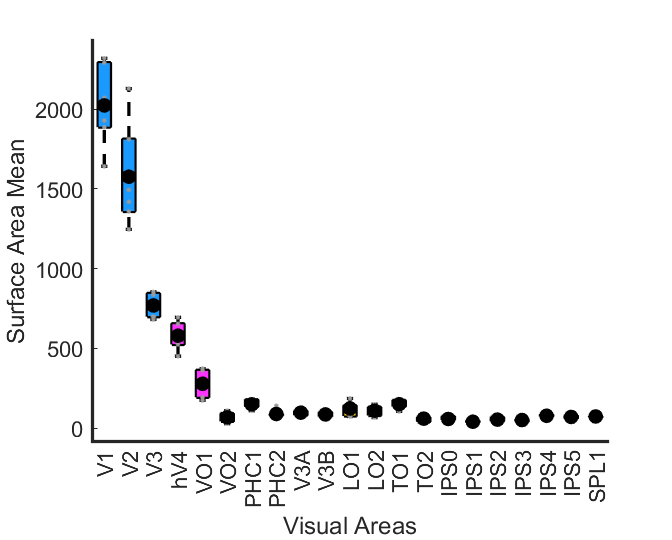

figure();
hold on
h=boxplot(sum_monkey','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),(colorscale_monkey_all_inv(j,:)),'FaceAlpha',1);
end
hold on
cscale = zeros(size(colorscale_monkey_all,1),3);
plotSpread(sum_monkey','distributionColors',cscale+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(sum_monkey'),'k.','MarkerSize',30);

xlim([0.5 size(sum_monkey,1)+.5])
yticks(0:500:2000)
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
ax.FontSize = 13;
set(gca,'xtick',[1:length(alllabels_human)],'xticklabel', alllabels_human);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);

for i = 1:size(sum_monkey,1)
    area_range(i) = max(sum_monkey(i,:),[],'omitnan')/min(sum_monkey(i,:),[],'omitnan');
end

temp_rois = {1:4,ventralrois_monkey,dorsalrois_monkey,lateralrois_monkey,parietalrois_monkey};
for i = 1:length(temp_rois)
    disp(mean(area_range(temp_rois{i}),'all','omitnan'))
end

    1.4779

    2.1750

    2.3891

    1.9784

    1.8049



## Fig 2B

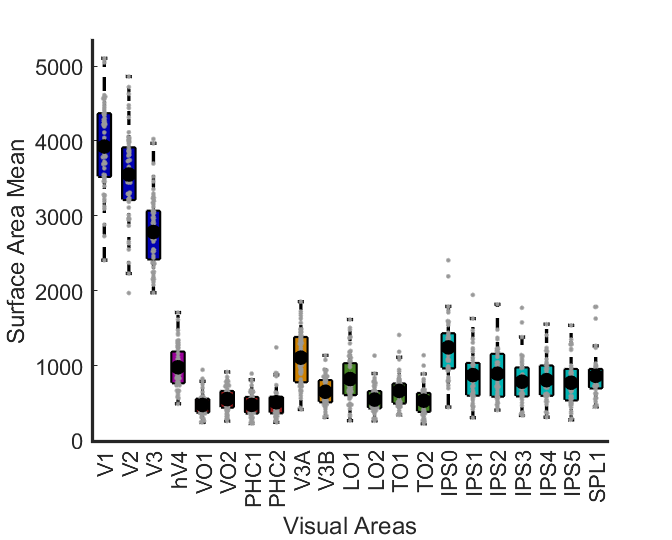

figure();
hold on
h=boxplot(sum_human','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),(colorscale_human_all_inv(j,:)),'FaceAlpha',1);
end
hold on
plotSpread(sum_human','distributionColors',colorscale_human_all*0+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(sum_human'),'k.','MarkerSize',30);
xlim([0.5 size(sum_human,1)+.5])
yticks(0:1000:5000)

ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
ax.FontSize = 13;
set(gca,'xtick',[1:length(alllabels_human)],'xticklabel', alllabels_human);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);

for i = 1:size(sum_human,1)
    area_range(i) = max(sum_human(i,:),[],'omitnan')/min(sum_human(i,:),[],'omitnan');
end

temp_rois = {1:4,ventralrois_human,dorsalrois_human,lateralrois_human,parietalrois_human};
for i = 1:length(temp_rois)
    disp(mean(area_range(temp_rois{i}),'all','omitnan'))
end

    2.5291

    4.1158

    4.0719

    4.9064

    5.1527



## Fig 2C

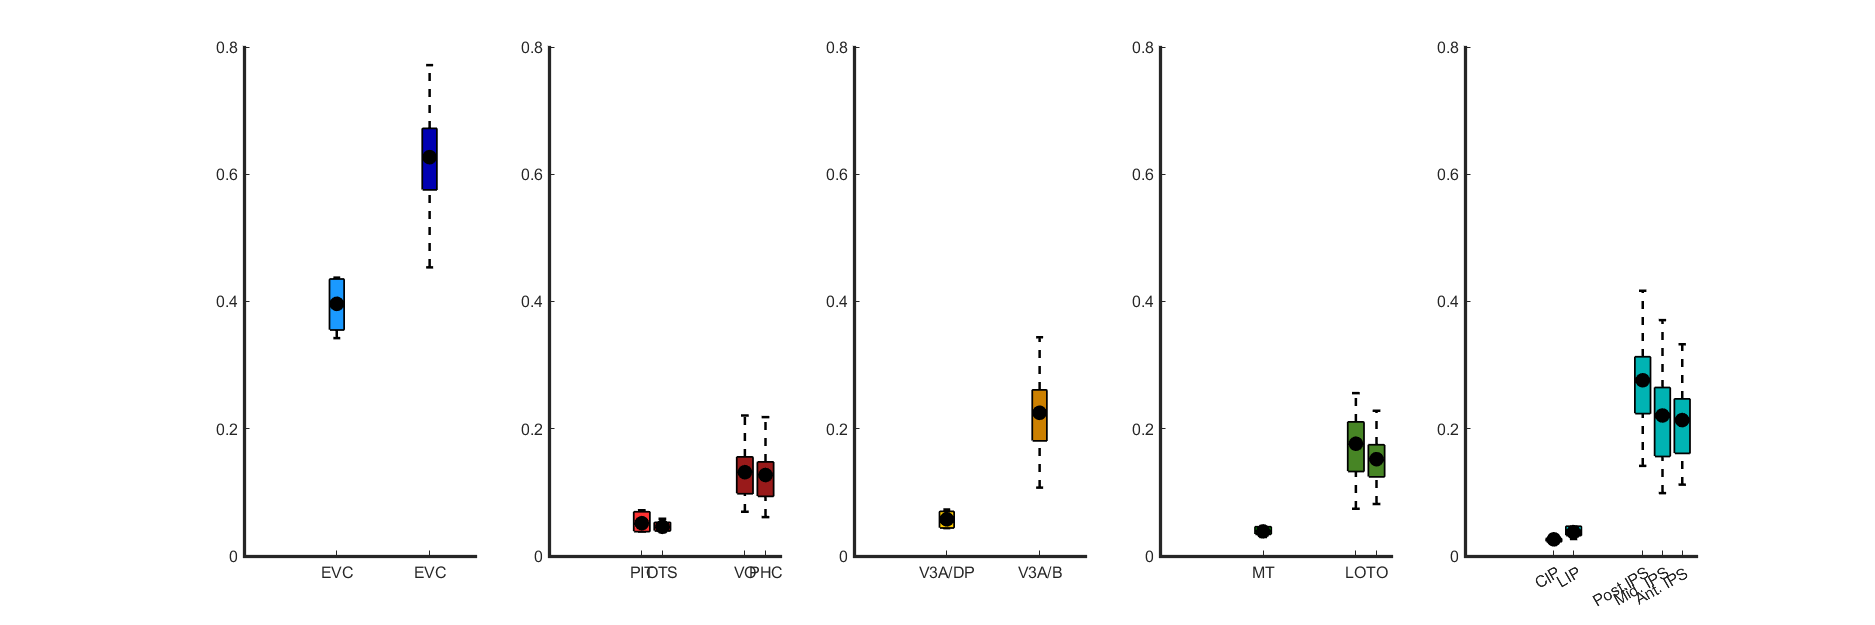

map_clusters_human = {mean(normv1_human(2:4,:),1,'omitnan'),[mean(normv1_human(5:6,:),1,'omitnan');mean(normv1_human(7:8,:),1,'omitnan')],...
    mean(normv1_human(9:10,:),1,'omitnan'),[mean(normv1_human(11:12,:),1,'omitnan');mean(normv1_human(13:14,:),1,'omitnan')],...
    [mean(normv1_human(15:16,:),1,'omitnan');mean(normv1_human(17:18,:),1,'omitnan');mean(normv1_human(19:21,:),1,'omitnan')]};
cluster_name_human = {'EVC',{'VO','PHC'},'V3A/B',{'LO','TO'},{'Post.IPS','Mid. IPS','Ant. IPS'}};
cluster_color_human = [colorscale_region_human(1,:);colorscale_region_human(5:end,:)];

map_clusters_monkey = {mean(normv1_monkey(2:5,:),1,'omitnan'),[mean(normv1_monkey(6:8,:),1,'omitnan');mean(normv1_monkey(9:10,:),1,'omitnan')],...
    mean(normv1_monkey(11:12,:),1,'omitnan'),mean(normv1_monkey(13:16,:),1,'omitnan'),...
    [mean(normv1_monkey(17:18,:),1,'omitnan');mean(normv1_monkey(19:21,:),1,'omitnan')]};
cluster_name_monkey = {'EVC',{'PIT','OTS'},'V3A/DP','MT',{'CIP','LIP'}};
cluster_color_monkey = [colorscale_region_monkey(1,:);colorscale_region_monkey(5:end,:)];

figure('Renderer', 'painters', 'Position', [10 10 1500 500]);
for i = 1:length(map_clusters_human)
    subplot(1,length(map_clusters_human),i);hold on;
    if size(map_clusters_monkey{i},1)==1
        h1 = boxplot(map_clusters_monkey{i}','colors',[0 0 0],'symbol','','Widths',0.15);
        set(h1,{'linew'},{1.5})
        h1 = findobj(gca,'Tag','Box');
        patch(get(h1,'XData'),get(h1,'YData'),cluster_color_monkey(i,:),'FaceAlpha',1);
        plot(1,nanmean(map_clusters_monkey{i}),'k.','MarkerSize',30);
        xt = 1;
    else
        h1 = boxplot([map_clusters_monkey{i}(1,:)',map_clusters_monkey{i}(2,:)'],[0.9, 1.1],'colors',[0 0 0],'symbol','','positions',[0.9, 1.1],'Widths',0.15);
        set(h1,{'linew'},{1.5})
        h1 = findobj(gca,'Tag','Box');
        patch(get(h1(1),'XData'),get(h1(1),'YData'),cluster_color_monkey(i,:),'FaceAlpha',1);
        patch(get(h1(2),'XData'),get(h1(2),'YData'),cluster_color_monkey(i,:),'FaceAlpha',1);
        plot([0.9 1.1],nanmean([map_clusters_monkey{i}(1,:)',map_clusters_monkey{i}(2,:)']),'k.','MarkerSize',30);
        xt = [0.9 1.1];
    end
    
    if size(map_clusters_human{i},1)==1
        h2 = boxplot(map_clusters_human{i}',2,'colors',[0 0 0],'symbol','','positions',2,'Widths',0.15);
        set(h2,{'linew'},{1.5})
        h2 = findobj(gca,'Tag','Box');
        patch(get(h2(1),'XData'),get(h2(1),'YData'),cluster_color_human(i,:),'FaceAlpha',1);
        plot(2,nanmean(map_clusters_human{i}),'k.','MarkerSize',30);
        xticks([xt 2])
        xticklabels({cluster_name_monkey{i},cluster_name_human{i}})
    elseif size(map_clusters_human{i},1)==2
        h2 = boxplot([map_clusters_human{i}(1,:)',map_clusters_human{i}(2,:)'],[1.9, 2.1],'colors',[0 0 0],'symbol','','positions',[1.9, 2.1],'Widths',0.15);
        set(h2,{'linew'},{1.5})
        h2 = findobj(gca,'Tag','Box');
        patch(get(h2(1),'XData'),get(h2(1),'YData'),cluster_color_human(i,:),'FaceAlpha',1);
        patch(get(h2(2),'XData'),get(h2(2),'YData'),cluster_color_human(i,:),'FaceAlpha',1);
        plot([1.9, 2.1],nanmean([map_clusters_human{i}(1,:)',map_clusters_human{i}(2,:)']),'k.','MarkerSize',30);
        xticks([xt 1.9 2.1])
        xticklabels([cluster_name_monkey{i},cluster_name_human{i}])
    else
        h2 = boxplot([map_clusters_human{i}(1,:)',map_clusters_human{i}(2,:)',map_clusters_human{i}(3,:)'],[1.8, 2, 2.2],'colors',[0 0 0],'symbol','','positions',[1.8, 2, 2.2],'Widths',0.15);
        set(h2,{'linew'},{1.5})
        h2 = findobj(gca,'Tag','Box');
        patch(get(h2(1),'XData'),get(h2(1),'YData'),cluster_color_human(i,:),'FaceAlpha',1);
        patch(get(h2(2),'XData'),get(h2(2),'YData'),cluster_color_human(i,:),'FaceAlpha',1);
        patch(get(h2(3),'XData'),get(h2(3),'YData'),cluster_color_human(i,:),'FaceAlpha',1);
        plot([1.8, 2, 2.2],nanmean([map_clusters_human{i}(1,:)',map_clusters_human{i}(2,:)',map_clusters_human{i}(3,:)']),'k.','MarkerSize',30);
        xticks([xt 1.8 2 2.2])
        xticklabels([cluster_name_monkey{i},cluster_name_human{i}])
    end
    box off;
    ax = gca;
    ax.XRuler.Axle.LineWidth = 2;
    ax.YRuler.Axle.LineWidth = 2;
    ylim([0 0.8])
    yticks(0:0.2:0.8)
end

## Fig 2D

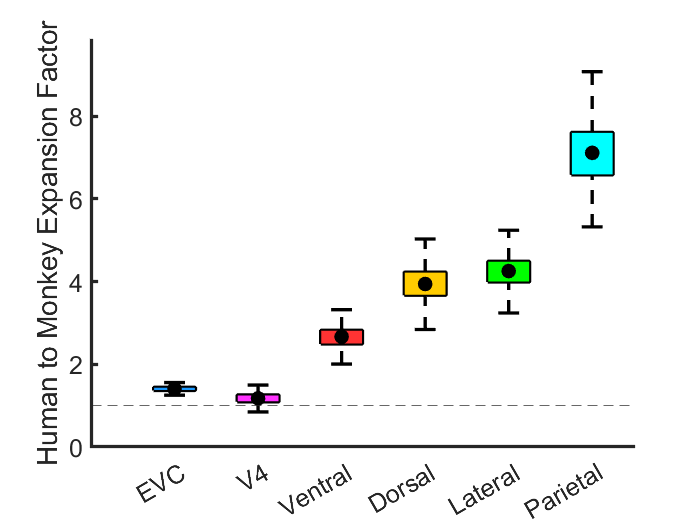

nResampling = 1000;
d = 1:size(cat_human,2);
temp_rois_human = {2:3,V4rois_human,ventralrois_human,dorsalrois_human,lateralrois_human,parietalrois_human};
temp_rois_monkey = {2:3,V4rois_monkey,ventralrois_monkey,dorsalrois_monkey,lateralrois_monkey,parietalrois_monkey};
data_monkey = zeros(length(temp_rois_human),nResampling);
for idx = 1:length(temp_rois_human)
    for res = 1:nResampling
        y = datasample(d,size(cat_monkey,2));
        data_monkey(idx,res) = mean(mean(cat_human(temp_rois_human{idx},y)./cat_human(1,y),2,'omitnan'))./mean(mean(cat_monkey(temp_rois_monkey{idx},:)./cat_monkey(1,:),2,'omitnan'));
    end
end

figure();
hold on;
h1 = boxplot(data_monkey','colors',[0 0 0],'symbol','');
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');
for j=1:size(data_monkey,1)
   % have to extract x values from boxplot in order to set xlabels
   patch(get(h1(j),'XData'),get(h1(j),'YData'),colorscale_region_monkey_inv(j,:),'FaceAlpha',1);
end

for j=1:size(data_monkey,1)
   % have to extract x values from boxplot in order to set xlabels
   plot(j,mean(data_monkey(j,:),'omitnan'),'k.','MarkerSize',30);
end

ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
ax.LineWidth = 2;
ylabel('Human to Monkey Expansion Factor')
xticks(1:6)
xticklabels(alllabels_combined)
yline(1,'--')
box off;

## Fig 3A

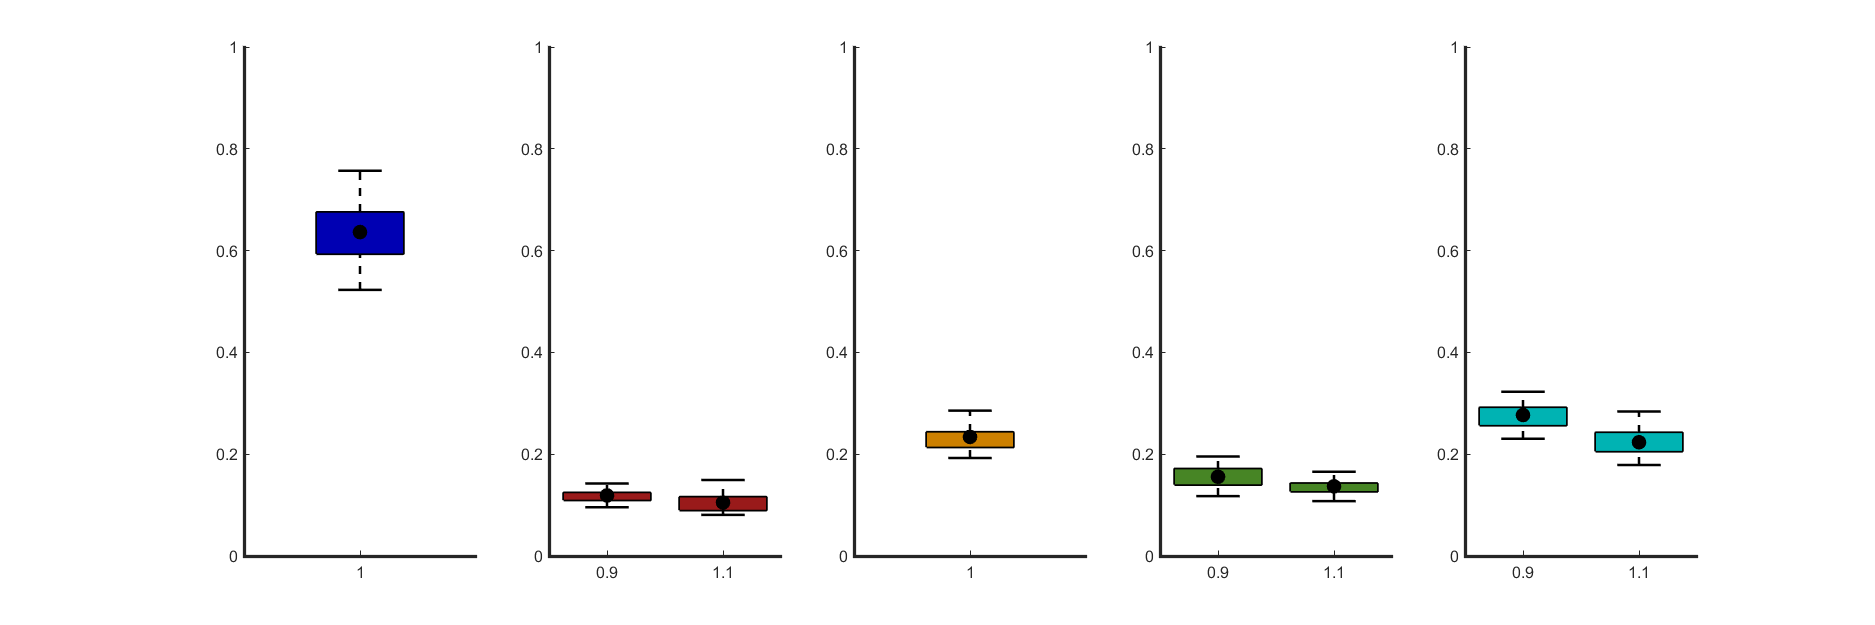

normv1_neo = sum_neo./sum_neo(1,:);

map_clusters_neo = {mean(normv1_neo(2:4,:),1,'omitnan'),[mean(normv1_neo(5:6,:),1,'omitnan');mean(normv1_neo(7:8,:),1,'omitnan')],...
    mean(normv1_neo(9:10,:),1,'omitnan'),[mean(normv1_neo(11:12,:),1,'omitnan');mean(normv1_neo(13:14,:),1,'omitnan')],...
    [mean(normv1_neo(15:16,:),1,'omitnan');mean(normv1_neo(17:18,:),1,'omitnan');mean(normv1_neo(19:21,:),1,'omitnan')]};
cluster_name_neo = {'EVC',{'VO','PHC'},'V3A/B',{'LO','TO'},{'Post.IPS','Mid. IPS','Ant. IPS'}};
cluster_color_neo = [colorscale_region_human(1,:);colorscale_region_human(5:end,:)];

figure('Renderer', 'painters', 'Position', [10 10 1500 500]);
for i = 1:length(map_clusters_human)
    subplot(1,length(map_clusters_human),i);hold on;
    if size(map_clusters_neo{i},1)==1
        h1 = boxplot(map_clusters_neo{i}','colors',[0 0 0],'symbol','','Widths',0.15);
        set(h1,{'linew'},{1.5})
        h1 = findobj(gca,'Tag','Box');
        patch(get(h1,'XData'),get(h1,'YData'),cluster_color_neo(i,:),'FaceAlpha',1);
%         plotSpread(map_clusters_neo{i}','xValues',1,'distributionColors',[.6 .6 .6],'spreadWidth',.2)
        plot(1,nanmean(map_clusters_neo{i}),'k.','MarkerSize',30);
        xt = 1;
    else
        h1 = boxplot([map_clusters_neo{i}(1,:)',map_clusters_neo{i}(2,:)'],[0.9, 1.1],'colors',[0 0 0],'symbol','','positions',[0.9, 1.1],'Widths',0.15);
        set(h1,{'linew'},{1.5})
        h1 = findobj(gca,'Tag','Box');
        patch(get(h1(1),'XData'),get(h1(1),'YData'),cluster_color_neo(i,:),'FaceAlpha',1);
        patch(get(h1(2),'XData'),get(h1(2),'YData'),cluster_color_neo(i,:),'FaceAlpha',1);
%         plotSpread(map_clusters_neo{i}(1,:)','xValues',0.9,'distributionColors',[.6 .6 .6],'spreadWidth',.2)
%         plotSpread(map_clusters_neo{i}(2,:)','xValues',1.1,'distributionColors',[.6 .6 .6],'spreadWidth',.2)
        plot([0.9 1.1],nanmean([map_clusters_neo{i}(1,:)',map_clusters_neo{i}(2,:)']),'k.','MarkerSize',30);
        xt = [0.9 1.1];
    end
    box off;
    ax = gca;
    ax.XRuler.Axle.LineWidth = 2;
    ax.YRuler.Axle.LineWidth = 2;
    yticks(0:0.2:1)
    ylim([0 1])
    xlim([0.8 1.2])
end

## Supp Fig 4

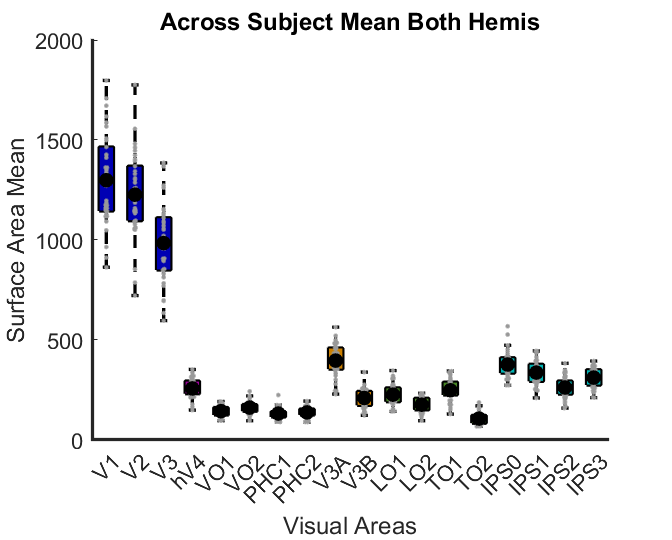

figure
hold on
h=boxplot(sum_neo(1:end-3,:)','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),(colorscale_human_all_inv(j+3,:)),'FaceAlpha',1);
end
hold on
plotSpread(sum_neo(1:end-3,:)','distributionColors',colorscale_human_all(4:end,:)*0+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(sum_neo(1:end-3,:)'),'k.','MarkerSize',30);
xlim([0.5 size(sum_neo(1:end-3,:),1)+.5])
ylim([0 2000])
yticks(0:500:2000)
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
ax.FontSize = 13;
set(gca,'xtick',[1:length(alllabels_human)],'xticklabel', alllabels_human);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
title('Across Subject Mean Both Hemis')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);

## Fig 3B

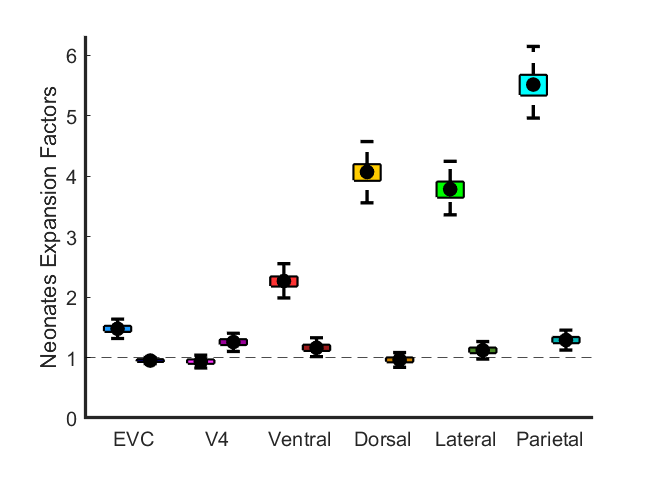

temp_rois_human = {2:3,V4rois_human,ventralrois_human,dorsalrois_human,lateralrois_human,parietalrois_human};
temp_rois_monkey = {2:3,V4rois_monkey,ventralrois_monkey,dorsalrois_monkey,lateralrois_monkey,parietalrois_monkey};

nResampling = 1000;
d_neo = 1:size(sum_neo,2);
d_human = 1:size(sum_human,2);
data_monkey = zeros(length(temp_rois_human),nResampling);
data_human = zeros(length(temp_rois_human),nResampling);
for idx = 1:length(temp_rois_human)
    for res = 1:nResampling
        y = datasample(d_neo,size(sum_monkey,2));
        data_monkey(idx,res) = mean(mean(sum_neo(temp_rois_human{idx},y)./sum_neo(1,y),2,'omitnan'))./mean(mean(sum_monkey(temp_rois_monkey{idx},:)./sum_monkey(1,:),2,'omitnan'));
        y = datasample(d_human,size(sum_neo,2));
        data_human(idx,res) = mean(mean(sum_human(temp_rois_human{idx},y)./sum_human(1,y),2,'omitnan'))./mean(mean(sum_neo(temp_rois_human{idx},:)./sum_neo(1,:),2,'omitnan'));
    end
end

concat_data = [];
concat_colorscale = [];
for i = 1:size(data_human,1)
    concat_data = [concat_data; data_monkey(i,:); data_human(i,:)];
    concat_colorscale = [concat_colorscale; colorscale_region_human_inv(i,:); colorscale_region_monkey_inv(i,:)];
end

g1 = sort([1:6,1:6]);
g2 = repmat(1:2,[1,6]);


figure('Renderer', 'painters', 'Position', [10 10 1500 500]);
hold on
h1=boxplot(concat_data',[g1' g2'],'factorgap',5,'colors',[0 0 0],'symbol','','Widths',0.8);
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');
for j=1:size(concat_data,1)
   % have to extract x values from boxplot in order to set xlabels
   xdat{j} = get(h1(j),'XData');
   xd(j) = (xdat{j}(3)+xdat{j}(2))/2;
   patch(get(h1(j),'XData'),get(h1(j),'YData'),concat_colorscale(j,:),'FaceAlpha',1);
end

% plotSpread(concat_data','xValues',fliplr(xd),'distributionColors',concat_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(fliplr(xd),nanmean(concat_data'),'k.','MarkerSize',30);
yline(1,'k--')

% take average of x values for each area to put xticklabel in the middle
xt = [];
for i = 1:length(xd)/2
    xt(i) = (xd(2*i-1) + xd(2*i))/2;
end

ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',fliplr(xt),'xticklabel', alllabels_combined,'fontsize',12);
% xlabel('Visual Areas');
ylabel('Neonates Expansion Factors');
% title('Normalization by Combined V1 Surface Area')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
ylim([0 6.3])

## Fig 4A

for i = 1:size(sum_human,1)
    norm_std_human(i) = std(sum_human(i,:),'omitnan')/mean(sum_human(i,:),'omitnan');
end

for i = 1:size(sum_monkey,1)
    norm_std_monkey(i) = std(sum_monkey(i,:),'omitnan')/mean(sum_monkey(i,:),'omitnan');
end

all_norm_std = {norm_std_human norm_std_monkey};
groups = {ones(length(norm_std_human),1) ones(length(norm_std_monkey),1)*2};
[p,h,stats] = ranksum(norm_std_human,norm_std_monkey)

p = 0.0011

h = logical
   1


stats = struct with fields:
       zval: 3.2702
    ranksum: 582



for i = 1:10000
    samp = randi(size(sum_human,2),size(sum_monkey,2),1);
    norm_std_resamp = std(sum_human(:,samp),[],2,'omitnan')./mean(sum_human(:,samp),2,'omitnan');
    norm_std_resamp(norm_std_resamp==0) = nan;
    p(i) = ranksum(norm_std_resamp,norm_std_monkey);
end
disp(mean(p))

    0.2990



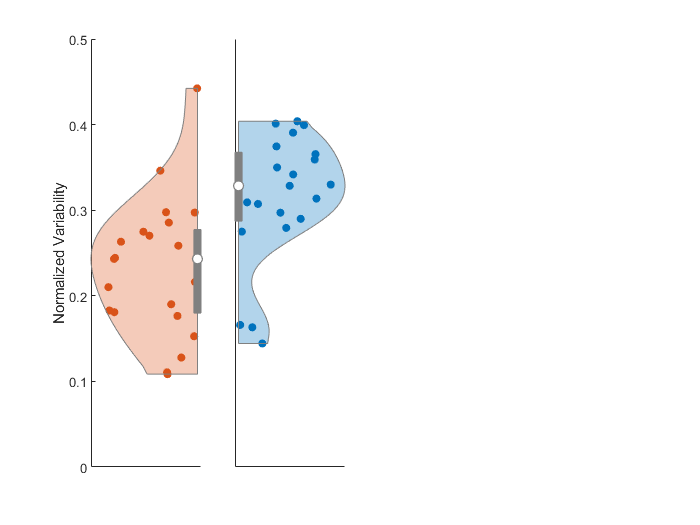


figure();
subplot(1,4,2)
violinplot(all_norm_std{1},groups{1},'HalfViolin','right','ViolinColor',human_blue);
% ylabel('Normalized Variability')
% xticks([1,2])
% xticklabels('Humans')
ylim([0 0.5])
xticks([])
yticks([])
box off;

subplot(1,4,1)
violinplot(all_norm_std{2},groups{2},'HalfViolin','left','ViolinColor',monkey_orange);
ylabel('Normalized Variability')
% xticks([1,2])
% xticklabels('Monkeys')
ylim([0 0.5])
yticks([0:0.1:0.5])
xticks([])
box off;

## Fig 4B

surfacearea_human_norm{1} = cat_human(:,1:62) ./ mean(cat_human(:,1:62),2,'omitnan');
surfacearea_human_norm{2} = cat_human(:,63:end) ./ mean(cat_human(:,63:end),2,'omitnan');

surfacearea_monkey_norm{1} = cat_monkey(:,1:6) ./ mean(cat_monkey(:,1:6),2,'omitnan');
surfacearea_monkey_norm{2} = cat_monkey(:,7:end) ./ mean(cat_monkey(:,7:end),2,'omitnan');

data1 = surfacearea_human_norm{1}-surfacearea_human_norm{2};
data2 = surfacearea_monkey_norm{1}-surfacearea_monkey_norm{2};

for i = 1:1000
    idx = datasample(1:size(data1,2),size(data2,2));
    data1_new = data1(:,idx);
    d1 = data1_new(:);d2 = data2(:);
    include1 = ~isnan(d1);include2 = ~isnan(d2);
    d1 = d1(include1);d2 = d2(include2);
    [h,p] = vartest2(d1,d2);
    all_p(i) = p;
end

disp(['Resampled Two Sample F Test: p = ',num2str(mean(all_p))])

Resampled Two Sample F Test: p = 0.0051791



nboot = 1000;
h_data = std(data1,[],2,'omitnan');
h_data_boot = bootstrp(nboot,@(x) std(x,[],2,'omitnan'),data1);
m_data = std(data2,[],2,'omitnan');
m_data_boot = bootstrp(nboot,@(x) std(x,[],2,'omitnan'),data2);

[p,h,stats] = ranksum(h_data,m_data)

p = 3.5411e-04

h = logical
   1


stats = struct with fields:
       zval: 3.5721
    ranksum: 594



for i = 1:10000
    samp = randi(size(data1,2),size(data2,2),1);
    norm_std_resamp = std(data1(:,samp),[],2,'omitnan');
    norm_std_resamp(norm_std_resamp==0) = nan;
    p(i) = ranksum(norm_std_resamp,std(data2,[],2,'omitnan'));
end
disp(mean(p))

    0.1788



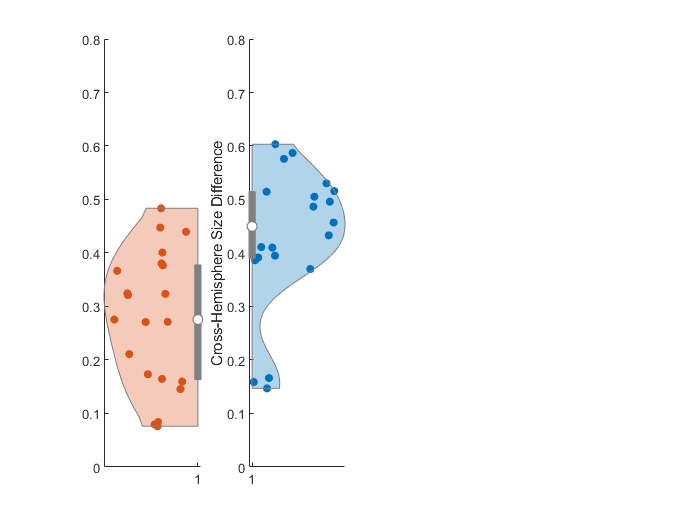


figure();
subplot(1,4,2)
violinplot(h_data,ones(1,length(h_data))','HalfViolin','right','ViolinColor',human_blue);
ylabel('Cross-Hemisphere Size Difference')
% xticks([1,2])
% xticklabels('Humans')
ylim([0 0.8])
% yticks(-2:1:2)
box off;

subplot(1,4,1)
violinplot(m_data,ones(1,length(m_data))','HalfViolin','left','ViolinColor',monkey_orange);
% ylabel('Normalized Variability')
% xticks([1,2])
% xticklabels('Monkeys')
ylim([0 0.8])
% yticks(-2:1:2)
box off;

## Fig 4C

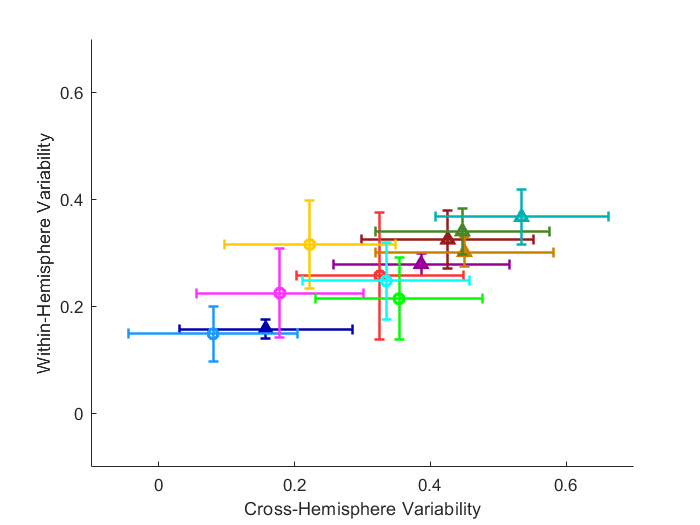

res_fun = @(x) max(x,[],'omitnan')/min(x,[],'omitnan');

norm_sum_dv_human = sum_human./(sum_human(1,:));
for i = 1:size(sum_human,1)
    norm_std_human(i) = std(sum_human(i,:),'omitnan')/mean(sum_human(i,:),'omitnan');
    norm_ci_human(i,:) = bootci(1000,res_fun,sum_human(i,:));
    std_boot_human(i,:) = bootstrp(1000,@(x) std(x,'omitnan')/mean(x,'omitnan'),sum_human(i,:));
end

norm_sum_dv_monkey = sum_monkey./sum_monkey(1,:);
for i = 1:size(sum_monkey,1)
    norm_std_monkey(i) = std(sum_monkey(i,:),'omitnan')/mean(sum_monkey(i,:),'omitnan');
    norm_ci_monkey(i,:) = bootci(1000,res_fun,sum_monkey(i,:));
    std_boot_monkey(i,:) = bootstrp(1000,@(x) std(x,'omitnan')/mean(x,'omitnan'),sum_monkey(i,:));
end

figure();
hold on;
for i = 1:size(colorscale_unique_human,1)
plot(mean(h_data(region_rois_human{i})),mean(norm_std_human(region_rois_human{i})),'-^','Color',colorscale_unique_human(i,:),'LineWidth',2)
all_err = h_data_boot(:,region_rois_human{i});
all_err = all_err(:);
errorbar(mean(h_data(region_rois_human{i})),mean(norm_std_human(region_rois_human{i})),std(all_err),'horizontal','Color',colorscale_unique_human(i,:),'LineWidth',1.5)
all_err = std_boot_human(region_rois_human{i},:);
all_err = all_err(:);
errorbar(mean(h_data(region_rois_human{i})),mean(norm_std_human(region_rois_human{i})),std(all_err),'vertical','Color',colorscale_unique_human(i,:),'LineWidth',1.5)

plot(mean(m_data(region_rois_monkey{i})),mean(norm_std_monkey(region_rois_monkey{i})),'-o','Color',colorscale_unique_monkey(i,:),'LineWidth',2)
all_err = m_data_boot(:,region_rois_monkey{i});
all_err = all_err(:);
errorbar(mean(m_data(region_rois_monkey{i})),mean(norm_std_monkey(region_rois_monkey{i})),std(all_err),'horizontal','Color',colorscale_unique_monkey(i,:),'LineWidth',1.5)
all_err = std_boot_monkey(region_rois_monkey{i},:);
all_err = all_err(:);
errorbar(mean(m_data(region_rois_monkey{i})),mean(norm_std_monkey(region_rois_monkey{i})),std(all_err),'vertical','Color',colorscale_unique_monkey(i,:),'LineWidth',1.5)
end
xlim([-0.1 0.7])
xticks([0:0.2:0.6])
ylim([-0.1 0.7])
yticks([0:0.2:0.6])
xlabel('Cross-Hemisphere Variability')
ylabel('Within-Hemisphere Variability')

## Fig 5A

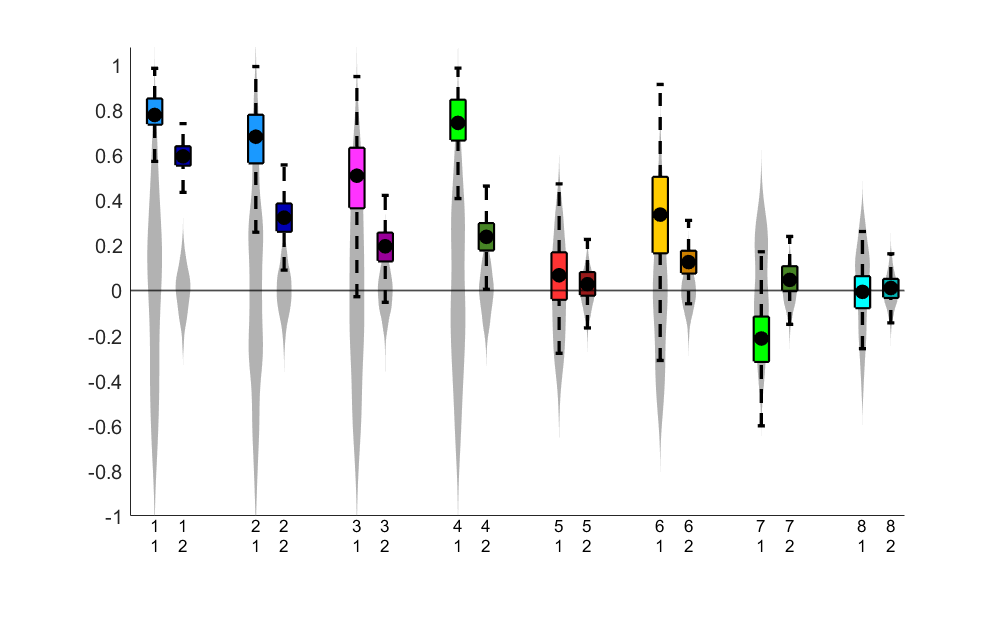

areas_human = {cat_human(2,:),cat_human(3,:),cat_human(4,:),cat_human(13,:),cat_human(5:8,:),cat_human(9:10,:),cat_human([11:12,14],:),cat_human(15:21,:)};
areas_monkey = {cat_monkey(2,:),cat_monkey(3,:),cat_monkey(4,:),cat_monkey(13,:),...
    cat_monkey(6:10,:),cat_monkey(11:12,:),cat_monkey(14:16,:),cat_monkey(17:21,:)};


r_human = [];
% r_human_mean = [];
r_human_boot = {};
p_human = [];
r_monkey = [];
% r_monkey_mean = [];
r_monkey_boot = {};
p_monkey = [];
r_perm_human = {};
r_perm_monkey = {};
for i = 1:length(areas_human)
    r_human(i) = mean(corr(areas_human{i}',cat_human(1,:)','Rows','complete'));
    r_human_boot{i} = bootstrp(1000,@(x,y) mean(corr(x,y,'Rows','complete')),areas_human{i}',cat_human(1,:)');
    
    r_monkey(i) = mean(corr(areas_monkey{i}',cat_monkey(1,:)','Rows','complete'));
    r_monkey_boot{i} = bootstrp(1000,@(x,y) mean(corr(x,y,'Rows','complete')),areas_monkey{i}',cat_monkey(1,:)');
    for j = 1:1000
        nSub_human = size(cat_human,2)/2;
        idx1 = randperm(nSub_human);
        idx2 = randperm(nSub_human);
        r_perm_human{i}(j) = mean(corr(areas_human{i}(:,[idx1 idx1+nSub_human])',cat_human(1,:)','Rows','complete'));
%         r_perm_human{i}(j) = mean(corr(areas_human{i}(:,[idx1 idx1+nSub_human])',cat_human(1,[idx2 idx2+nSub_human])','Rows','complete'));
        
        nSub_monkey = size(cat_monkey,2)/2;
        idx1 = randperm(nSub_monkey);
        idx2 = randperm(nSub_monkey);
%         r_perm_monkey{i}(j) = mean(corr(areas_monkey{i}(:,[idx1 idx1+nSub_monkey])',cat_monkey(1,[idx2 idx2+nSub_monkey])','Rows','complete'));
        r_perm_monkey{i}(j) = mean(corr(areas_monkey{i}(:,[idx1 idx1+nSub_monkey])',cat_monkey(1,:)','Rows','complete'));
    end
%     p_human(i) = signtest(r_human_boot{i},0,'Tail','both');
%     [~,p] = ttest(r_human_boot{i});
%     p_human(i) = p;
%     [~,p] = ttest2(r_human_boot{i},r_perm_human{i}','Vartype','unequal');
%     p_human(i) = p;
%     p_human(i) = ranksum(r_human_boot{i},r_perm_human{i}');
%     p = anova1([r_human_boot{i} r_perm_human{i}']);
    CI95_human = mean(r_perm_human{i}) + 1.64*(std(r_perm_human{i}));
    p_human95(i) = mean(r_human(i))>CI95_human;
    CI975_human = mean(r_perm_human{i}) + 1.96*(std(r_perm_human{i}));
    p_human975(i) = mean(r_human(i))>CI975_human;

%     p_monkey(i) = signtest(r_monkey_boot{i},0,'Tail','both');
%     [~,p] = ttest(r_monkey_boot{i});
%     p_monkey(i) = p;
%     [~,p] = ttest2(r_monkey_boot{i},r_perm_monkey{i}','Vartype','unequal');
%     p_monkey(i) = p;
%     p_monkey(i) = ranksum(r_monkey_boot{i},r_perm_monkey{i}');
%     p = anova1([r_monkey_boot{i} r_perm_monkey{i}']);
    CI95_monkey = mean(r_perm_monkey{i}) + 1.64*(std(r_perm_monkey{i}));
    p_monkey95(i) = mean(r_monkey(i))>CI95_monkey;
    CI975_monkey = mean(r_perm_monkey{i}) + 1.96*(std(r_perm_monkey{i}));
    p_monkey975(i) = mean(r_monkey(i))>CI975_monkey;
end

mx = 1:3:3*8;hx = 2:3:3*8+1;
h_color = [colorscale_region_human([2:4,7],:);colorscale_region_human(5:end,:)];
m_color = [colorscale_region_monkey([2:4,7],:);colorscale_region_monkey(5:end,:)];

rvals = [];
bootvals = [];
cvals = [];
permvals = [];
for i = 1:length(areas_human)
    rvals = [rvals r_monkey(i) r_human(i)];
    bootvals = [bootvals r_monkey_boot{i} r_human_boot{i}];
    cvals = [cvals; m_color(i,:); h_color(i,:)];
    permvals = [permvals; r_perm_monkey{i}; r_perm_human{i}];
end

g1 = sort([1:8,1:8]);
g2 = repmat(1:2,[1,8]);
cvals = flipud(cvals);

figure('Renderer', 'painters', 'Position', [10 10 800 500]);hold on;
yline(0,'k-','LineWidth',1)

h1 = boxplot(bootvals,[g1' g2'],'factorgap',[13 1],'colors',[0 0 0],'symbol','');

% calculate whether the mean is outside the 97.5 CI
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');
for j=1:size(cvals,1)
   temp = get(h1(j),'XData');
   violin(permvals(size(permvals,1)-j+1,:)','x',(temp(1)+temp(3))/2,'edgecolor','none','facecolor',[0.4 0.4 0.4],'mc',[],'medc',[]);
end

h1 = boxplot(bootvals,[g1' g2'],'factorgap',[13 1],'colors',[0 0 0],'symbol','');
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');

for j=1:size(cvals,1)
   % have to extract x values from boxplot in order to set xlabels
   patch(get(h1(j),'XData'),get(h1(j),'YData'),cvals(j,:),'FaceAlpha',1);
end

xd = [];
for j=1:size(cvals,1)
    i = size(cvals,1)+1-j;
   % have to extract x values from boxplot in order to set xlabels
   xdat{j} = get(h1(j),'XData');
   xd(j) = (xdat{j}(3)+xdat{j}(2))/2;
   plot(xd(j),rvals(i),'k.','MarkerSize',30);
end

box off;

## Fig 5B

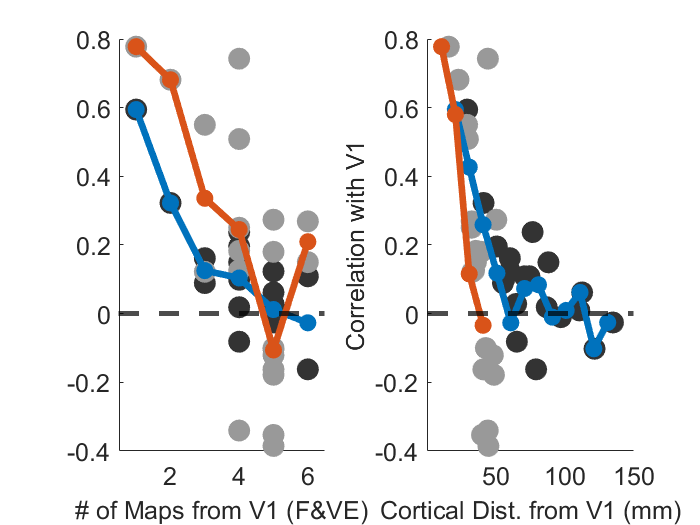

meanmonks_cortdist_rh=nanmean(monkey_data.avgdist_allsubjs_rh,2);
meanmonks_cortdist_lh=nanmean(monkey_data.avgdist_allsubjs_lh,2);

meanmonks_cortdist_rh1234=[];
meanmonks_cortdist_rh1234(1)=[meanmonks_cortdist_rh(1)+meanmonks_cortdist_rh(2)];
meanmonks_cortdist_rh1234(2)=[meanmonks_cortdist_rh(3)+meanmonks_cortdist_rh(4)]/2;
meanmonks_cortdist_rh1234(3)=[meanmonks_cortdist_rh(5)+meanmonks_cortdist_rh(6)]/2;
meanmonks_cortdist_rh1234(4)=[meanmonks_cortdist_rh(7)+meanmonks_cortdist_rh(8)]/2;
meanmonks_cortdist_rh1234(5)=[meanmonks_cortdist_rh(9)+meanmonks_cortdist_rh(10)]/2;
meanmonks_cortdist_rh1234=[meanmonks_cortdist_rh1234,meanmonks_cortdist_rh(11:end)'];

meanmonks_cortdist_lh1234=[];
meanmonks_cortdist_lh1234(1)=[meanmonks_cortdist_lh(1)+meanmonks_cortdist_lh(2)];
meanmonks_cortdist_lh1234(2)=[meanmonks_cortdist_lh(3)+meanmonks_cortdist_lh(4)]/2;
meanmonks_cortdist_lh1234(3)=[meanmonks_cortdist_lh(5)+meanmonks_cortdist_lh(6)]/2;
meanmonks_cortdist_lh1234(4)=[meanmonks_cortdist_lh(7)+meanmonks_cortdist_lh(8)]/2;
meanmonks_cortdist_lh1234(5)=[meanmonks_cortdist_lh(9)+meanmonks_cortdist_lh(10)]/2;
meanmonks_cortdist_lh1234=[meanmonks_cortdist_lh1234,meanmonks_cortdist_lh(11:end)'];

meanmonks_cortdist1234=[meanmonks_cortdist_lh1234+meanmonks_cortdist_lh1234]/2;

dist_from_v1_rh = human_data.dist_from_v1_rh;
dist_from_v1_lh = human_data.dist_from_v1_lh;

meanhumans_cortdist_rh = mean(dist_from_v1_rh,2,'omitnan');
meanhumans_cortdist_lh = mean(dist_from_v1_lh,2,'omitnan');

meanhumans_cortdist_rh1234=[];
meanhumans_cortdist_rh1234(1)=0;
meanhumans_cortdist_rh1234(2)=[meanhumans_cortdist_rh(3)+meanhumans_cortdist_rh(4)]/2;
meanhumans_cortdist_rh1234(3)=[meanhumans_cortdist_rh(5)+meanhumans_cortdist_rh(6)]/2;
meanhumans_cortdist_rh1234=[meanhumans_cortdist_rh1234,meanhumans_cortdist_rh(7:end)'];

meanhumans_cortdist_lh1234=[];
meanhumans_cortdist_lh1234(1)=0;
meanhumans_cortdist_lh1234(2)=[meanhumans_cortdist_lh(3)+meanhumans_cortdist_lh(4)]/2;
meanhumans_cortdist_lh1234(3)=[meanhumans_cortdist_lh(5)+meanhumans_cortdist_lh(6)]/2;
meanhumans_cortdist_lh1234=[meanhumans_cortdist_lh1234,meanhumans_cortdist_lh(7:end)'];

meanhumans_cortdist1234=[meanhumans_cortdist_lh1234+meanhumans_cortdist_lh1234]/2;

human_areadistfromV1 = human_data.areadistfromV1;
human_fellemanhierarchy = human_data.fellemanhierarchy;

monk_areadistfromV1= monkey_data.areadistfromV1;
monk_fellemanhierarchy= monkey_data.fellemanhierarchy;

human_v1_corr = zeros(1,size(cat_human,1));
monkey_v1_corr = zeros(1,size(cat_monkey,1));
human_v1_corr_ci = zeros(size(cat_human,1),10000);
monkey_v1_corr_ci = zeros(size(cat_monkey,1),10000);
for ii = 1:size(cat_human,1)
    exclude_nan = find(~isnan(cat_human(ii,:)));
    SA_area = cat_human(ii,exclude_nan);
    SA_v1 = cat_human(1,exclude_nan);
    human_v1_corr(ii) = corr2(SA_area,SA_v1);
    
    exclude_nan = find(~isnan(cat_monkey(ii,:)));
    SA_area = cat_monkey(ii,exclude_nan);
    SA_v1 = cat_monkey(1,exclude_nan);
    monkey_v1_corr(ii) = corr2(SA_area,SA_v1);
end

for x = 1:max([monk_fellemanhierarchy,human_fellemanhierarchy])
    human_meanhierarchydist(x)=nanmean(human_v1_corr(human_fellemanhierarchy==x)); 
    monk_meanhierarchydist(x)=nanmean(monkey_v1_corr(monk_fellemanhierarchy==x));
end

stepsize=10;
maxrange=150;
human_meancortdist=nan(length(1:stepsize:maxrange),1);
monk_meancortdist=nan(length(1:stepsize:maxrange),1);
count = 0;
for x = 1:stepsize:maxrange
    count = count+1;
    if x < 150
        if sum([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)]) > 1
            monk_meancortdist(count)=nanmean(monkey_v1_corr([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<x+stepsize]));
        elseif sum([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)])
            monk_meancortdist(count)=monkey_v1_corr([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)]);
        end
        if sum([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]) > 1
            human_meancortdist(count)=nanmean(human_v1_corr([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]));
        elseif sum([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)])
            human_meancortdist(count)=human_v1_corr([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]);
        end
    end
end
human_meancortdist(4)=[human_meancortdist(3)+human_meancortdist(5)]/2;

figure();
subplot(1,2,1)
hold on
plot(human_fellemanhierarchy(2:end),human_v1_corr(2:end),'.','color',[.2 .2 .2],'MarkerSize',45)
plot(monk_fellemanhierarchy(2:end),monkey_v1_corr(2:end),'.','color',[.6 .6 .6],'MarkerSize',45) 
plot(human_meanhierarchydist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0 0.4470 0.7410])
plot(monk_meanhierarchydist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0.8500 0.3250 0.0980])
yline(0,'k--','LineWidth',3)
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
xlim([0.5 max([monk_fellemanhierarchy,human_fellemanhierarchy])+.5])
xlabel('# of Maps from V1 (F&VE)','Fontsize',15)

subplot(1,2,2) 
hold on
plot(meanhumans_cortdist1234(2:end),human_v1_corr(2:end),'.','color',[.2 .2 .2],'MarkerSize',45)
plot(meanmonks_cortdist1234(2:end),monkey_v1_corr(2:end),'.','color',[.6 .6 .6],'MarkerSize',45) 
plot(1:stepsize:maxrange,human_meancortdist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0 0.4470 0.7410])
plot(1:stepsize:maxrange,monk_meancortdist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0.8500 0.3250 0.0980])
yline(0,'k--','LineWidth',3)
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
xlim([0.5 150])
xlabel('Cortical Dist. from V1 (mm)','fontsize',15)
ylabel('Correlation with V1','fontsize',15)

## Fig 6A&C

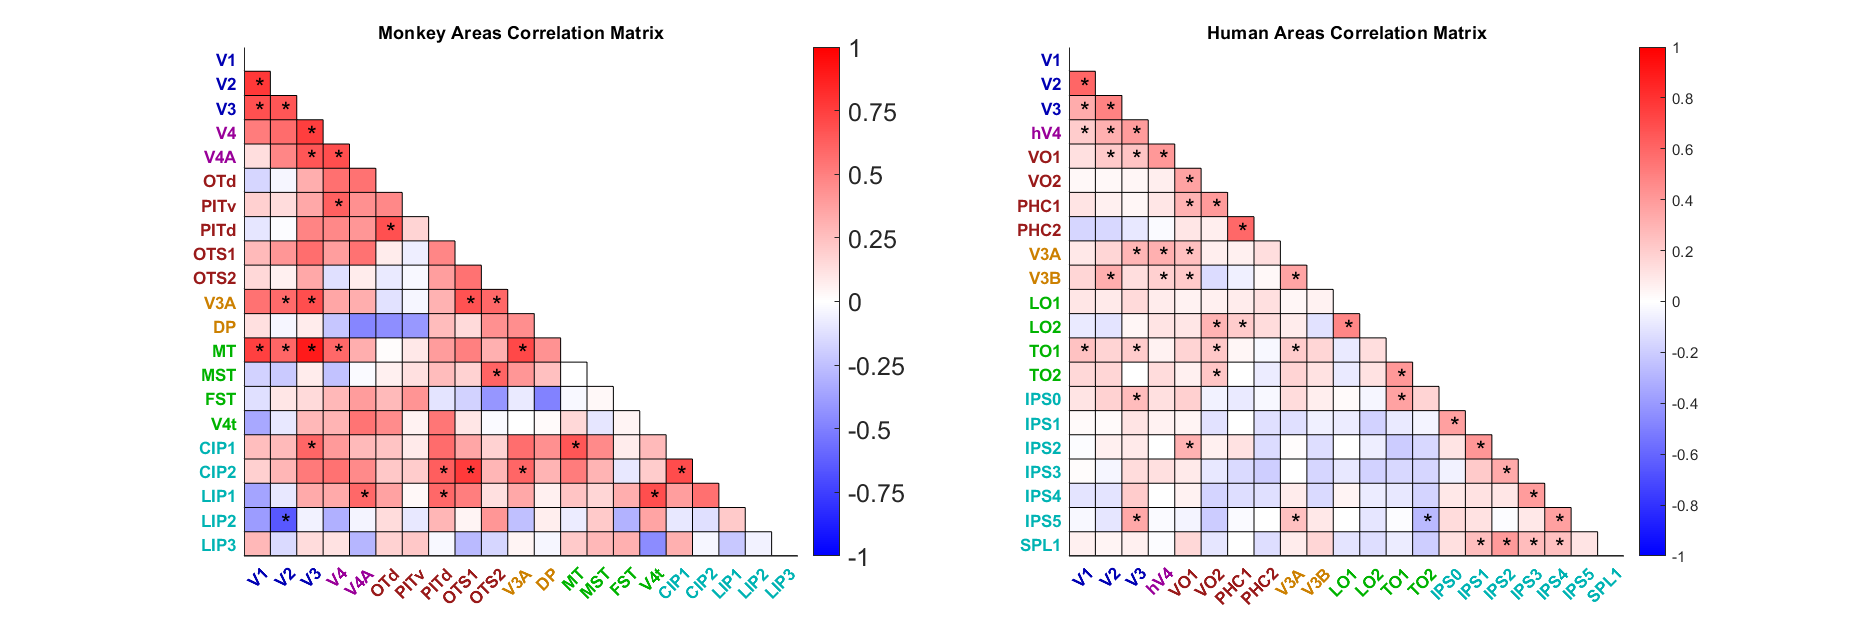

all_area_corr_human = zeros(length(alllabels_human),length(alllabels_human));
all_area_pval_human = zeros(length(alllabels_human),length(alllabels_human));
for i = 1:length(alllabels_human)
    for j = 1:length(alllabels_human)
        include = ~isnan(cat_human(i,:)) & ~isnan(cat_human(j,:));
        [r,p] = corr(cat_human(i,include)',cat_human(j,include)');
        all_area_pval_human(i,j) = p;
        all_area_corr_human(i,j) = r;
    end
end

all_area_corr_monkey = zeros(length(alllabels_monkey),length(alllabels_monkey));
all_area_pval_monkey = zeros(length(alllabels_monkey),length(alllabels_monkey));
for i = 1:length(alllabels_monkey)
    for j = 1:length(alllabels_monkey)
        include = ~isnan(cat_monkey(i,:)) & ~isnan(cat_monkey(j,:));
        [r,p] = corr(cat_monkey(i,include)',cat_monkey(j,include)');
        all_area_pval_monkey(i,j) = p;
        all_area_corr_monkey(i,j) = r;
    end
end

EVCcolor=[0 0 0.7];
V4color=[0.6 0 0.6];
ventralcolor=[0.6 0.1 0.1];
dorsalcolor=[0.8 .5 0]; % added V7, idk if that's right
lateralcolor=[0 0.7 0];
parietalcolor=[0 0.7 0.7];
frontalcolor=[.4 0 .4];

figure('Renderer', 'painters', 'Position', [10 10 1500 500]);
subplot(1,2,1);
Z = ones(size(all_area_corr_monkey,1), size(all_area_corr_monkey,2), 3);  %black background
image(Z);
hold on;
lower_tri = tril(all_area_corr_monkey);
lower_tri(1:length(lower_tri)+1:end) = 0;
alphadata = double(lower_tri ~= 0);
p_tri = tril(all_area_pval_monkey);
p_tri(p_tri == 0) = 1;
p_tri(1:length(p_tri)+1:end) = 1;

h2 = imagesc(all_area_corr_monkey);
h2.AlphaData = alphadata;
% hold off
for i = 1:size(all_area_corr_monkey,1)
    for j = 1:size(all_area_corr_monkey,2)
        if p_tri(j,i)<0.05
            text(i-0.1,j+0.1,'*','FontSize',15)
        end
        if j < length(all_area_corr_monkey)
        plot([j+0.5 j+0.5],[j+0.5 length(all_area_corr_monkey)+0.5],'k')
        end
    end
    plot([i+0.5 0],[i+0.5 i+0.5],'k')    
end

% Xticklabels = get(gca,'XDisplayLabels');
Xticklabels_new = cell(size(alllabels_monkey));
% Yticklabels = get(gca,'YDisplayLabels');
Yticklabels_new = cell(size(alllabels_monkey));
for i = 1:3
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], EVCcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], EVCcolor);
end
for i = 4:5
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], V4color);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], V4color);
end
for i = 6:10
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], ventralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], ventralcolor);
end
for i = 11:12
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], dorsalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], dorsalcolor);
end
for i = 13:16
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], lateralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], lateralcolor);
end
for i = 17:21
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], parietalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], parietalcolor);
end
ax = gca;
set(ax, 'XTick',1:length(alllabels_monkey),'XTickLabel',Xticklabels_new)
set(ax, 'YTick',1:length(alllabels_monkey),'YTickLabel',Yticklabels_new)
box off;
ax.XAxis.TickLength = [0 0];
ax.YAxis.TickLength = [0 0];
% set(ax,'xaxisLocation','top')
colormap(redblue);c = colorbar;caxis([-1 1]);c.Ticks = -1:0.25:1;c.FontSize = 15;

title('Monkey Areas Correlation Matrix')

subplot(1,2,2)
Z = ones(size(all_area_corr_human,1), size(all_area_corr_human,2), 3);  %black background
image(Z);
hold on;
lower_tri = tril(all_area_corr_human);
lower_tri(1:length(lower_tri)+1:end) = 0;
p_tri = tril(all_area_pval_human);
p_tri(p_tri == 0) = 1;
p_tri(1:length(p_tri)+1:end) = 1;
alphadata = double(lower_tri ~= 0);

h1 = imagesc(all_area_corr_human);
h1.AlphaData = alphadata;
% hold off
for i = 1:size(all_area_corr_human,1)
    for j = 1:size(all_area_corr_human,2)
        if p_tri(j,i)<0.05
            text(i-0.1,j+0.1,'*','FontSize',15)
        end
        if j < length(all_area_corr_human)
        plot([j+0.5 j+0.5],[j+0.5 length(all_area_corr_human)+0.5],'k')
        end
    end
    plot([i+0.5 0],[i+0.5 i+0.5],'k')
end
Xticklabels_new = cell(size(alllabels_human));
Yticklabels_new = cell(size(alllabels_human));
for i = 1:3
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], EVCcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], EVCcolor);
end
for i = 4
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], V4color);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], V4color);
end
for i = 5:8
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], ventralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], ventralcolor);
end
for i = 9:10
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], dorsalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], dorsalcolor);
end
for i = 11:14
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], lateralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], lateralcolor);
end
for i = 15:21
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], parietalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], parietalcolor);
end

ax = gca;
set(ax, 'XTick',1:length(alllabels_human),'XTickLabel',Xticklabels_new)
set(ax, 'YTick',1:length(alllabels_human),'YTickLabel',Yticklabels_new)
% set(ax,'xaxisLocation','top')
box off;
ax.XAxis.TickLength = [0 0];
ax.YAxis.TickLength = [0 0];

colormap(redblue);c = colorbar;caxis([-1 1]);
title('Human Areas Correlation Matrix')

## Fig 6B&D

monkey_prox_mat = load('C:\Users\eemeyer\Documents\GitHub\RetinoAreaComparisons\data\monkey_prox_mat.mat');
monkey_prox_mat = table2array(monkey_prox_mat.VisualAreaProximityMatrixS1);
monkey_prox_mat(15,13) = 2;
monkey_prox_mat(16,14) = 2;

human_prox_mat = load('C:\Users\eemeyer\Documents\GitHub\RetinoAreaComparisons\data\human_prox_mat.mat');
human_prox_mat = table2array(human_prox_mat.VisualAreaProximityMatrix);

monkey_corr_all = all_area_corr_monkey(:);
monkey_prox_all = monkey_prox_mat(:);

rem_zeros = monkey_prox_all~=0;
monkey_corr_all = monkey_corr_all(rem_zeros);
monkey_prox_all = monkey_prox_all(rem_zeros);

[p,h,stats] = ranksum(monkey_corr_all(monkey_prox_all==1),monkey_corr_all(monkey_prox_all==2))

p = 0.0542

h = logical
   0


stats = struct with fields:
       zval: 1.9256
    ranksum: 799


[p,h,stats] = ranksum(monkey_corr_all(monkey_prox_all==2),monkey_corr_all(monkey_prox_all==3))

p = 0.0820

h = logical
   0


stats = struct with fields:
       zval: 1.7390
    ranksum: 3158


[p,h,stats] = ranksum(monkey_corr_all(monkey_prox_all==1),monkey_corr_all(monkey_prox_all==3))

p = 8.5392e-05

h = logical
   1


stats = struct with fields:
       zval: 3.9287
    ranksum: 3231



figure(); 
subplot(1,2,1);hold on;
viol1 = violinplot(monkey_corr_all,monkey_prox_all,'ViolinColor',monkey_orange,'MedianMarkerSize',100);
yline(0,'k--')
ylim([-1 1])
yticks(-1:0.5:1)
box off;

human_corr_all = all_area_corr_human(:);
human_prox_all = human_prox_mat(:);

rem_zeros = human_prox_all~=0;
human_corr_all = human_corr_all(rem_zeros);
human_prox_all = human_prox_all(rem_zeros);

[p,h,stats] = ranksum(human_corr_all(human_prox_all==1),human_corr_all(human_prox_all==2))

p = 6.4314e-06

h = logical
   1


stats = struct with fields:
       zval: 4.5117
    ranksum: 957


[p,h,stats] = ranksum(human_corr_all(human_prox_all==2),human_corr_all(human_prox_all==3))

p = 0.0017

h = logical
   1


stats = struct with fields:
       zval: 3.1376
    ranksum: 3862


[p,h,stats] = ranksum(human_corr_all(human_prox_all==1),human_corr_all(human_prox_all==3))

p = 7.1129e-11

h = logical
   1


stats = struct with fields:
       zval: 6.5183
    ranksum: 3679


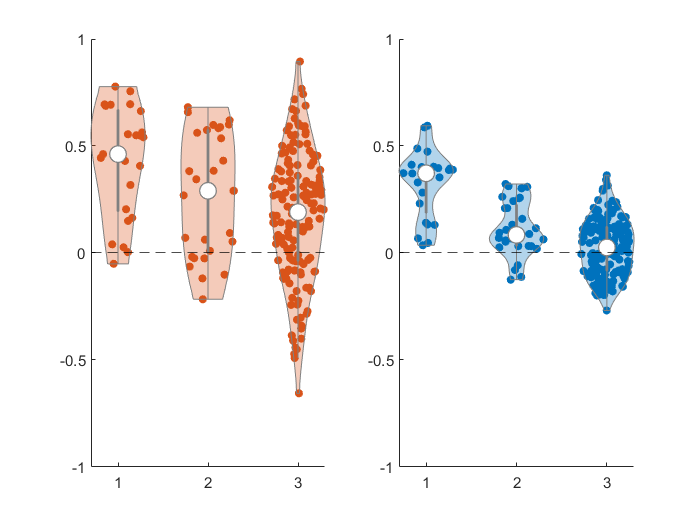


subplot(1,2,2); hold on;
viol1 = violinplot(human_corr_all,human_prox_all,'ViolinColor',human_blue,'MedianMarkerSize',100);
yline(0,'k--')
ylim([-1 1])
yticks(-1:0.5:1)
box off;